%Question 1
clc
clear all
a = input('Enter a vector');
c = length(a);
ad = 0;
for k  = 1:c;
    ad = ad + a(k);
end
ad

%Question 1
clc
clear all
a = input('Enter a vector');
c = length(a) + 1;
ad = 0;
k = 1;
while k < c
    ad = ad + a(k);
    k = k + 1;
end
ad

sum(a) == ad



%Question 2
clc
clear all
a = input('Enter 1st number');
b = input('Enter 2nd number');
c = input('Enter total numbers');
c = c-2;
fibo = [a b]

for k = 1:c
    
    fibo = [fibo , fibo(k) + fibo(k+1)]
end


fibo

%Question 3
clc
clear all
a = input('Enter 1st number');
b = input('Enter 2nd number');
c = input('Enter total numbers');
c = c-1;
fibo = [a b];
k = 1;

while k < c;
    
    fibo = [fibo , fibo(k) + fibo(k+1)];
    k = k+1;
end


fibo

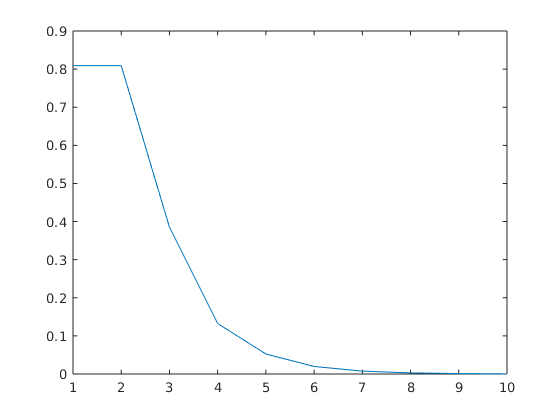

%Question 4
clc
clear all

a = input('Enter 1st number');
b = input('Enter 2nd number');

k = 1;
fibo= [a b];
fibo = [fibo , fibo(k) + fibo(k+1)];



j = 3;
fratio = abs(fibo(j)/fibo(j-1) - fibo(j-1)/fibo(j-2));
k = k + 1;

while fratio(end) > 0.001
    
    fibo = [fibo , fibo(k) + fibo(k+1)];
    
    fratio = [fratio fibo(j)/fibo(j-1) - fibo(j-1)/fibo(j-2)]; 
    fratio = abs(fratio);
   
    
   
    j = j+1;
    k = k +1;
end

plot(fratio)

%QUESTION 5
clc
clear all
a = input('Enter the number to test');
x = input('Enter the initial guess');
c = input('Enter the convergence criterion');

n = 1;

y(n) = 1/a * x.^2;
x(n + 1) = (x/8 * (15 - y(n)*(10 - 3*y(n))));

while abs(x(n+1) - x(n)) <= c
    y(n) = 1/a * x^2;
    x(n + 1) = (x/8 * (15 - y(n)*(10 - 3*y(n))));
end


sqrt(a) == round(x(n + 1))